Downsampling Run

[x, fs] = audioread('seashell.wav');

Play Sound

soundsc(x, fs);

Spectrogram of 'seashell.wav'. We createed a 3D plot to illustrate the spectrogram.

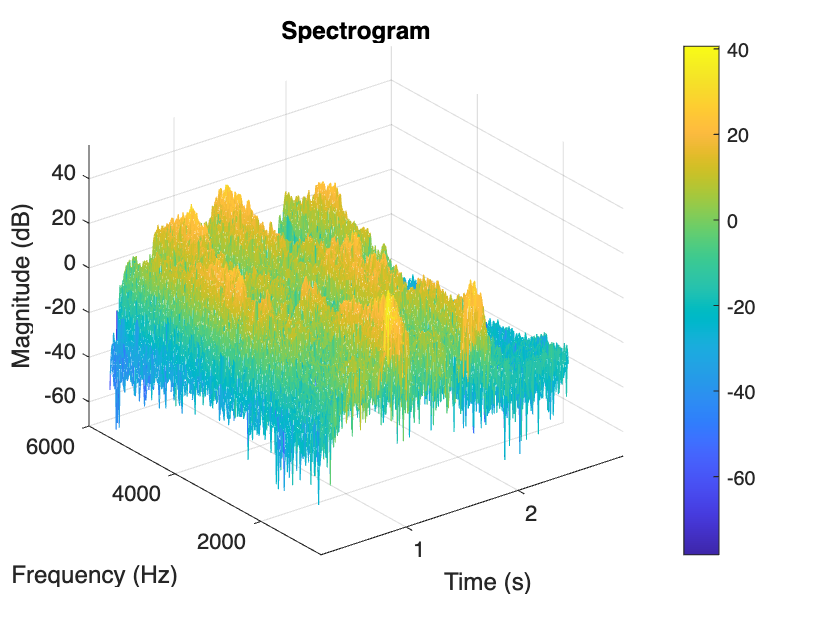

 plot_spectrogram(x, fs);

Now we decimate by a factor of 2 and show that there is aliasing. Decimating results in aliasing if certain conditions are not met, see eqn 6.15 in Holton DSP. Decimating by a factor of 2 is also equivalent to sampling at half of the sampling rate. So we play back the sound at about 5.5 kHz

x_decimate_2 = x(1:2:end);
soundsc(x_decimate_2, 5500); 

Compare to 'seadown_bad.wav', they should sound the same.

compare to seashell_bad.wav
[x_bad, fs_bad] = audioread('seadown_bad.wav');
soundsc(x_bad, fs_bad);

Plot spectrogram for the decimated signal. T